初期化

close all
clear

画像の準備

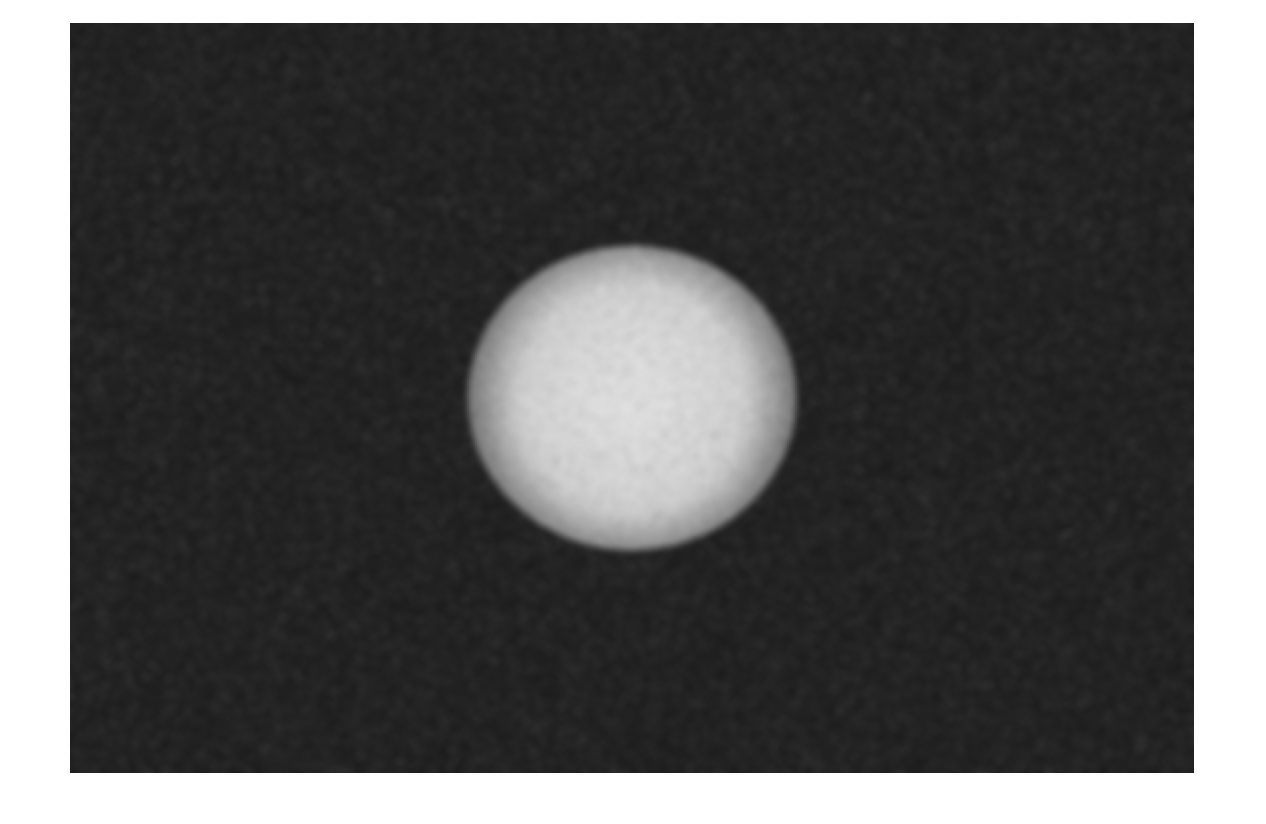

rgb = imread('fig.tif');
imshow(rgb)

円の直径計測

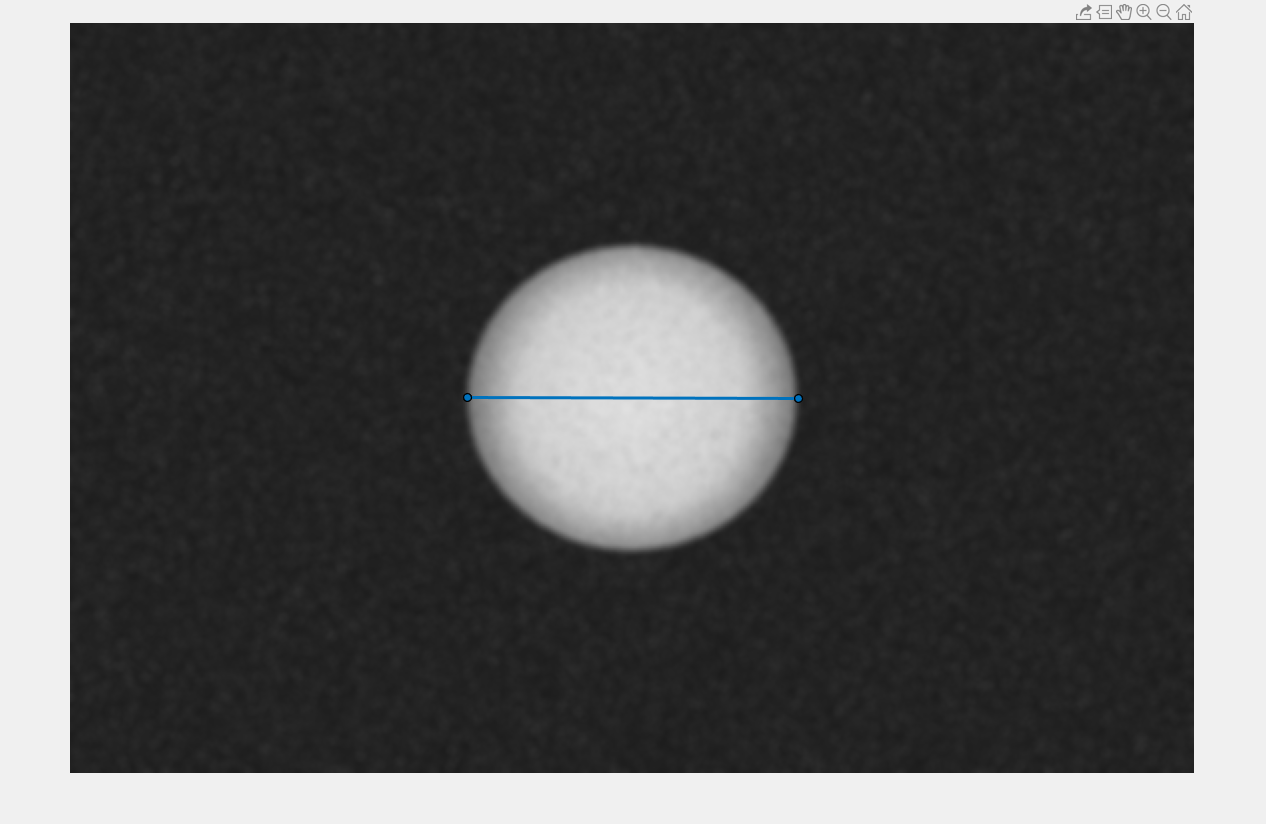

d = drawline;

pos = d.Position;
diffPos = diff(pos);
diameter = hypot(diffPos(1),diffPos(2))　%測ったｄの長さ＝直径

diameter = 496.5023

円検出

[centers,radii] = imfindcircles(rgb,[200 250],'ObjectPolarity','bright')

centers =   842.9685  562.8645


radii = 234.2382

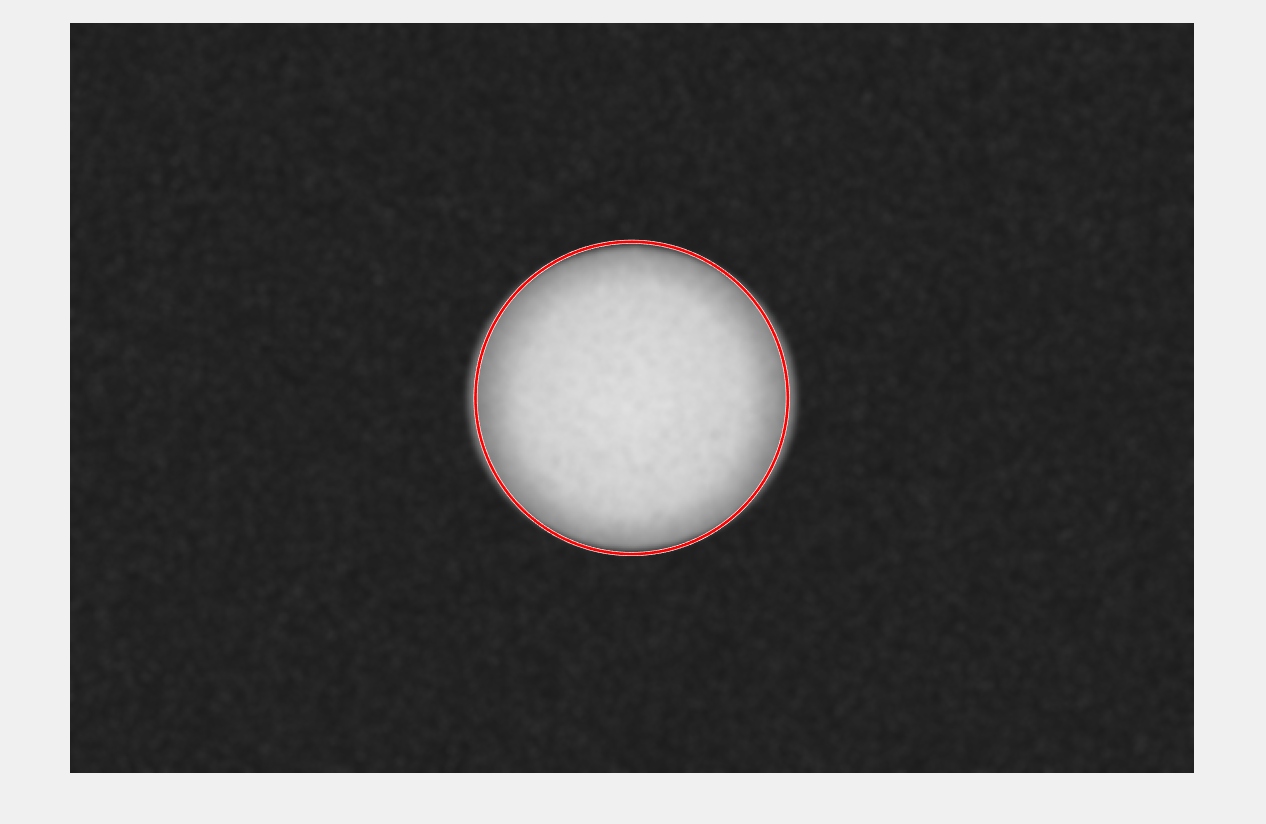

imshow(rgb)
h = viscircles(centers,radii);

画像に線を引いてプロファイル表示

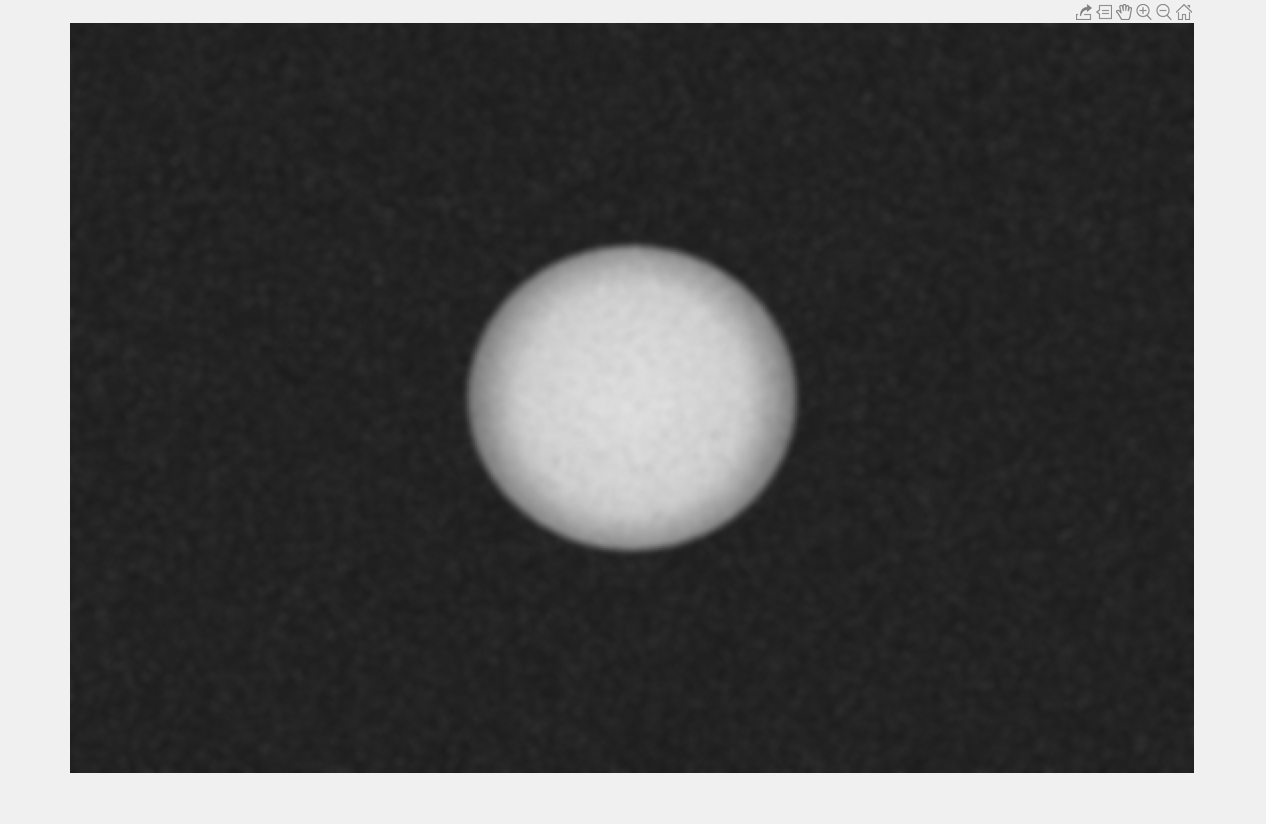

imshow(rgb)
p=improfile;

グラフ描画

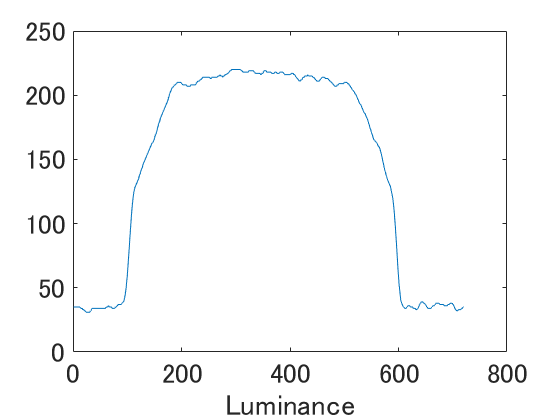

f1=figure;
plot(p)

xlabel("Distance along profile");
xlabel("Luminance");

ax=gca;
ax.FontSize=20;
saveas(f1,'plot_profile.png')